# Matrix and Array

## Exercise 1

V1 = [1 6 4 3]

V1 =      1     6     4     3


V2 = [4 2 pi 1]' %hochkomma ist transponieren der Matrize

V2 =     4.0000
    2.0000
    3.1416
    1.0000



time = 0:10

time =      0     1     2     3     4     5     6     7     8     9    10


time_ms = 0:1e-3:0.02

time_ms =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200



A = [1:3; 4:6]

A =      1     2     3
     4     5     6


B = [7:9; 10:12; 13:15]

B =      7     8     9
    10    11    12
    13    14    15



C = [A ; B]

C =      1     2     3
     4     5     6
     7     8     9
    10    11    12
    13    14    15


## Exercise 2

V = [9/11 12.6 100]

V =     0.8182   12.6000  100.0000


format rat
V

V =        9/11          63/5          100       


format long
V

V = 	1.0e+02 *

   0.008181818181818   0.126000000000000   1.000000000000000


format longEng
V

V =     818.181818181818e-003    12.6000000000000e+000    100.000000000000e+000


format
V

V =     0.8182   12.6000  100.0000


## Exercise 3


x = 1 + i*pi

x = 1.0000 + 3.1416i

size(A)

ans =      2     3


size(B)

ans =      3     3



sprintf('Size of A is %i rows and %i cols', size(A))

ans = 'Size of A is 2 rows and 3 cols'


sum(C)     %Spaltensumme

ans =     35    40    45


sum(C')'   %Zeilensumme

ans =      6
    15
    24
    33
    42




[min(C); max(C)]

ans =      1     2     3
    13    14    15


[min(C')' , max(C')']

ans =      1     3
     4     6
     7     9
    10    12
    13    15


## Exercise 4

a = 1:3, b = 4:6

a =      1     2     3


b =      4     5     6


log(a)

ans =          0    0.6931    1.0986



a*b'

ans = 32

a'*b

ans =      4     5     6
     8    10    12
    12    15    18



a.*b %Elementweise durch '.' Operator Multiplikation 2er Matrizen

ans =      4    10    18


a/b  %Lineare approximation 

ans = 0.4156

a./b

ans =     0.2500    0.4000    0.5000


a.^2 %Elementweise ^2

ans =      1     4     9


## Exercise 5

A = [1:10; 101:110; 201:210]

A =      1     2     3     4     5     6     7     8     9    10
   101   102   103   104   105   106   107   108   109   110
   201   202   203   204   205   206   207   208   209   210


B = A'

B =      1   101   201
     2   102   202
     3   103   203
     4   104   204
     5   105   205
     6   106   206
     7   107   207
     8   108   208
     9   109   209
    10   110   210



A(13)   %Daten werden spaltenweise gelesen/gespeichert

ans = 5

B(13)

ans = 103

A(2,3)  %rows, cols

ans = 103

B(2,3)

ans = 202

A(:,4) %Doppelpunkt -> alle Zeilen

ans =      4
   104
   204


B(2,:) 

ans =      2   102   202


B(3:6,2) 

ans =    103
   104
   105
   106


B([4 7 2 1],2) 

ans =    104
   107
   102
   101



find( (mod(A,2)==0) & (A>100) ) 

ans =      5
     6
    11
    12
    17
    18
    23
    24
    29
    30


find(mod(A,2)==0)

ans =      4
     5
     6
    10
    11
    12
    16
    17
    18
    22


(((A>100) & (mod(A,2)==0)) | A == 9) %logische Verknüpfungen

ans = 3×10 logical array
   0   0   0   0   0   0   0   0   1   0
   0   1   0   1   0   1   0   1   0   1
   0   1   0   1   0   1   0   1   0   1



indices = (((A>100) & (mod(A,2)==0)) | A == 9) %indices ist logische Matrix mit allen Elementen die Logik erfüllt

indices = 3×10 logical array
   0   0   0   0   0   0   0   0   1   0
   0   1   0   1   0   1   0   1   0   1
   0   1   0   1   0   1   0   1   0   1


A(indices)

ans =    102
   202
   104
   204
   106
   206
   108
   208
     9
   110


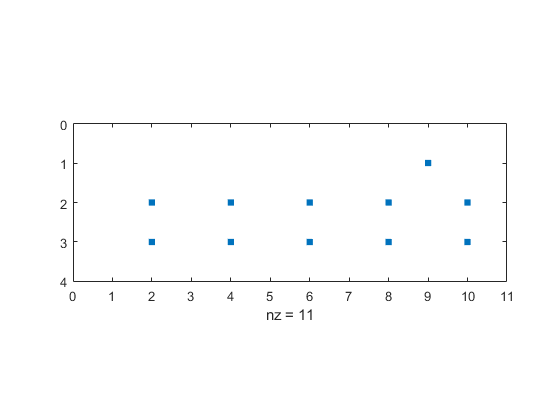

spy(indices)


A(2:3, 6:2:10)

ans =    106   108   110
   206   208   210



A(A<100) = A(A<100) + 300

A =    301   302   303   304   305   306   307   308   309   310
   101   102   103   104   105   106   107   108   109   110
   201   202   203   204   205   206   207   208   209   210
